# Boston Navi App

## INIT

clc;
clear all;
close all;
format long
%init_shapefile()
%[worldfile, shapefile] = calcWorldFile();

## Matfiles laden

Highways = load('Highways');
All = load('All');
Local = load('Local');


##  P1 Strassen darstellen

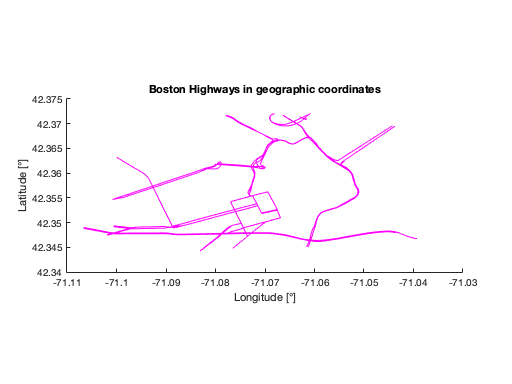

figure
mapshow(Highways.lon,Highways.lat, 'Color','m')
title('Boston Highways in geographic coordinates')
xlabel('Longitude [°]')
ylabel('Latitude [°]')

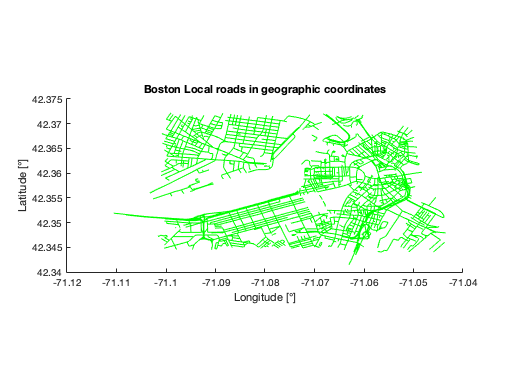

figure
mapshow(Local.lon,Local.lat, 'Color','g')
title('Boston Local roads in geographic coordinates')
xlabel('Longitude [°]')
ylabel('Latitude [°]')

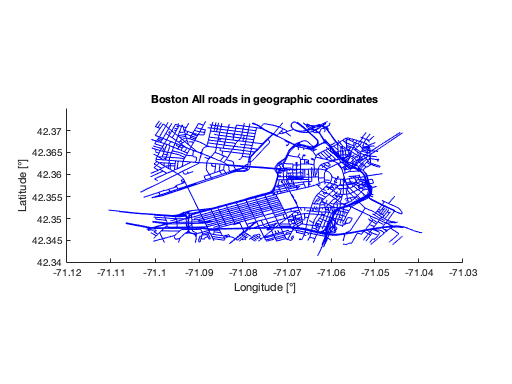

figure
mapshow(All.lon,All.lat, 'Color','b')
title('Boston All roads in geographic coordinates')
xlabel('Longitude [°]')
ylabel('Latitude [°]')

## P2 Karten georeferenzieren

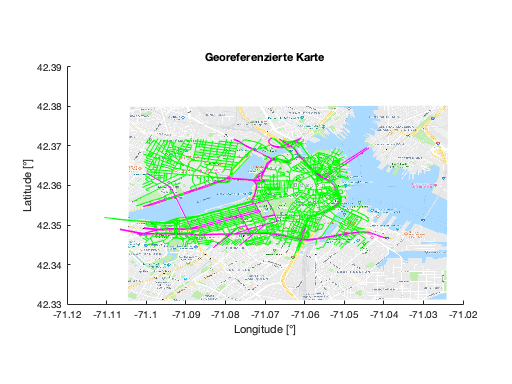

figure
mapshow('worldfile.PNG')
%hold on
%mapshow('roads_geo_out.shp')
hold on
mapshow(Highways.lon,Highways.lat, 'Color','m')
hold on
mapshow(Local.lon,Local.lat, 'Color','g')
title('Georeferenzierte Karte')
xlabel('Longitude [°]')
ylabel('Latitude [°]')

## Punkte durch User input einlesen

% Startpunkt waehlen
min_lon = min(All.lon); min_lat = min(All.lat);
max_lon = max(All.lon); max_lat = max(All.lat);
disp('Bitte Startpunkt mit Laengen- und Breitengrad angeben.')

Bitte Startpunkt mit Laengen- und Breitengrad angeben.


prompt_orig = ['\nBitte Laengengrad zwischen: ', num2str(min_lon), ...
    ' und ', num2str(max_lon), ' eingeben:\n' ];

start_lon = input(prompt_orig);
while start_lon < min_lon || start_lon > max_lon
    prompt = [num2str(start_lon), ' ist nicht gueltig. ', prompt_orig];
    start_lon = input(prompt);
end
prompt_orig = ['Bitte Breitengrad zwischen: ', num2str(min_lat), ...
    ' und ', num2str(max_lat), ' eingeben:\n' ];
start_lat = input(prompt_orig);
while start_lat < min_lat || start_lat > max_lat
    prompt = [num2str(start_lat), ' ist nicht gueltig. ', prompt_orig];
    start_lat = input(prompt);
end
disp(['Startpunkt gewaehlt: ', num2str(start_lon), ', ', num2str(start_lat)]);

Startpunkt gewaehlt: -71.1, 42.35


% Endpunkt waehlen
min_lon = min(All.lon); min_lat = min(All.lat);
max_lon = max(All.lon); max_lat = max(All.lat);
disp('Bitte Endpunkt mit Laengen- und Breitengrad angeben.')

Bitte Endpunkt mit Laengen- und Breitengrad angeben.


prompt_orig = ['\nBitte Laengengrad zwischen: ', num2str(min_lon), ...
    ' und ', num2str(max_lon), ' eingeben:\n' ];

end_lon = input(prompt_orig);
while end_lon < min_lon || end_lon > max_lon
    prompt = [num2str(end_lon), ' ist nicht gueltig. ', prompt_orig];
    end_lon = input(prompt);
end
prompt_orig = ['Bitte Breitengrad zwischen: ', num2str(min_lat), ...
    ' und ', num2str(max_lat), ' eingeben:\n' ];
end_lat = input(prompt_orig);
while end_lat < min_lat || end_lat > max_lat
    prompt = [num2str(end_lat), ' ist nicht gueltig. ', prompt_orig];
    end_lat = input(prompt);
end
disp(['Endpunktpunkt gewaehlt: ', num2str(start_lon), ', ', num2str(start_lat)]);

Endpunktpunkt gewaehlt: -71.1, 42.35


## P2 Eingegebene Koordinaten in NAD83 Koordinaten transformieren

proj = geotiffinfo('boston.tif');
[x_start,y_start] = projfwd(proj,start_lat, start_lon);
[x_end, y_end] = projfwd(proj, end_lat, end_lon);
